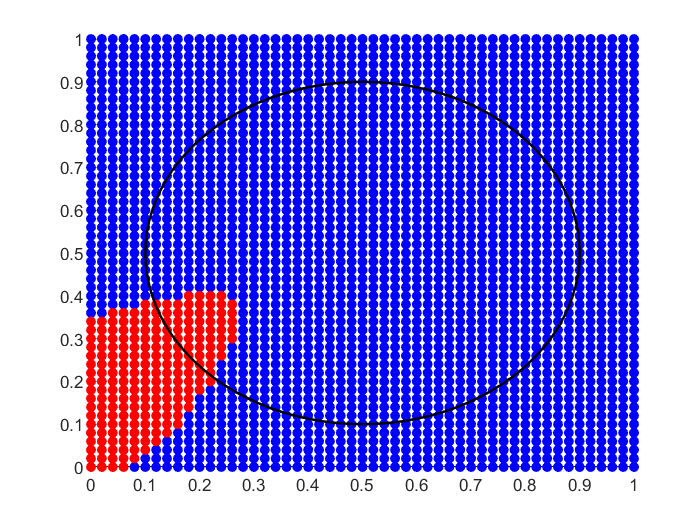

percentage_correct = 52.5567

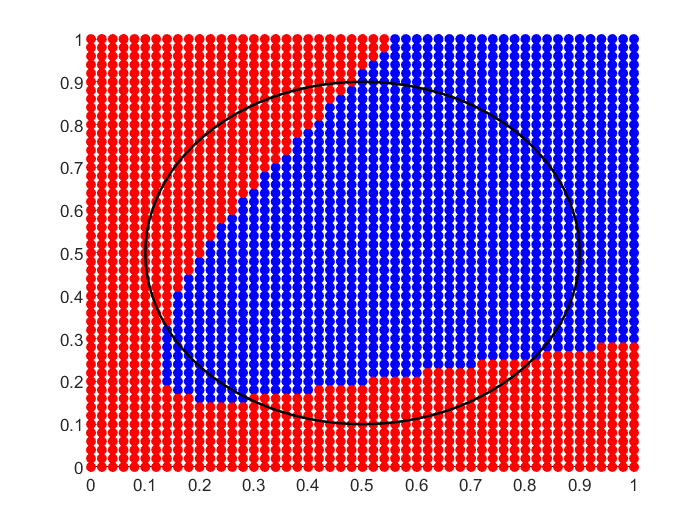

percentage_correct = 73.0873

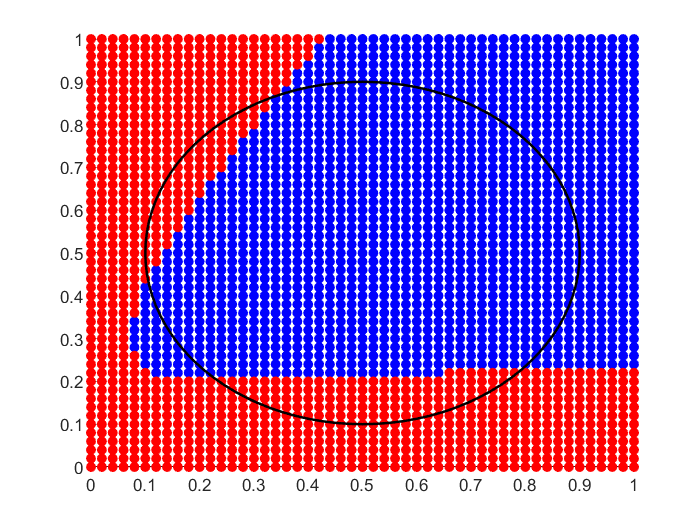

percentage_correct = 74.0869

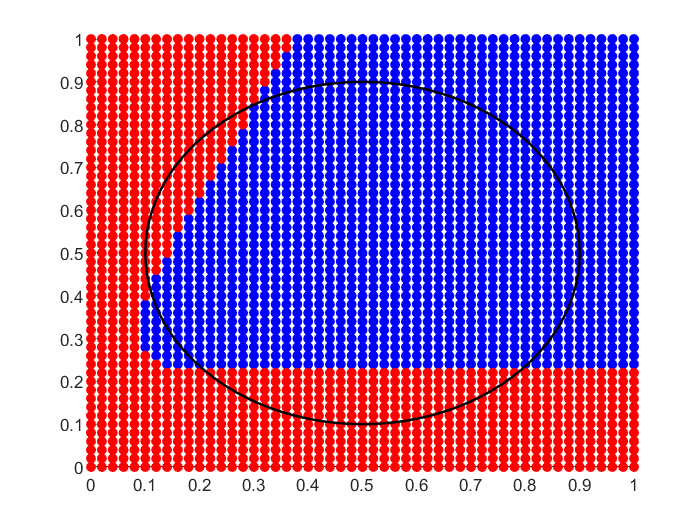

percentage_correct = 73.3180

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Cirkel");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_circle(grid);

% data to draw circle
th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;
    
% parameters
iterations = 10^6;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit, yunit,'black','LineWidth',1.5);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

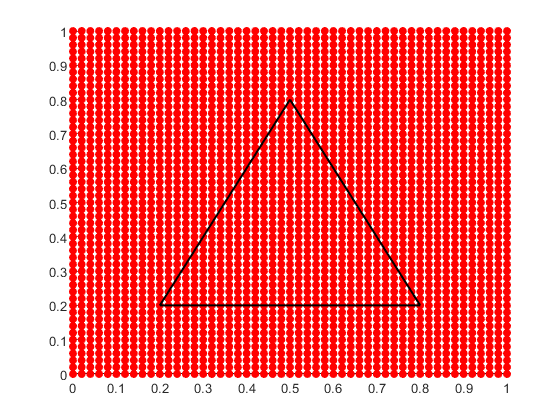

percentage_correct = 81.6993

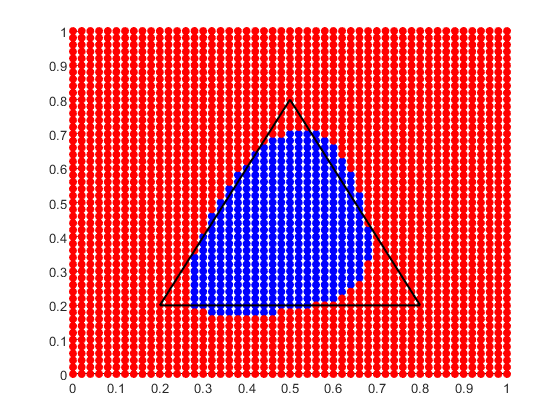

percentage_correct = 95.5402

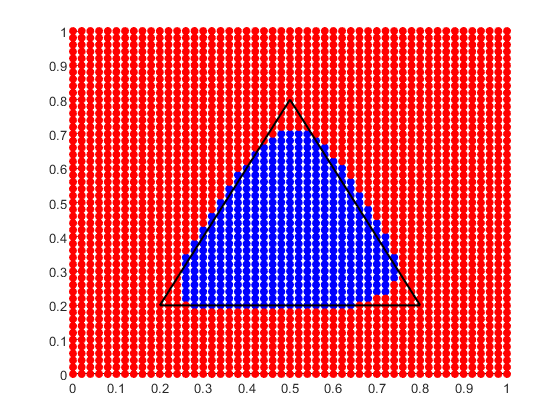

percentage_correct = 97.4241

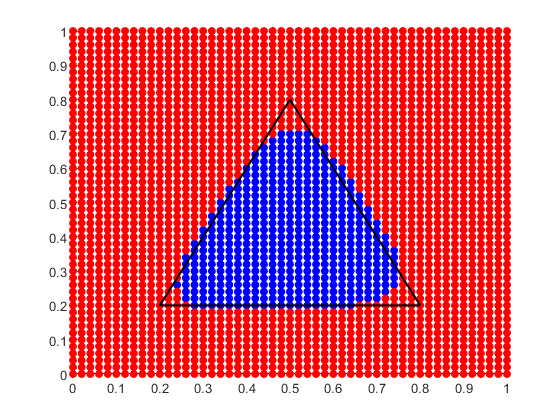

percentage_correct = 97.5394

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_triangle(grid);

xunit1 = linspace(0.2,0.8);
xunit2 = linspace(0.2,0.5);
xunit3 = linspace(0.5,0.8);
yunit1 = 0*xunit1 + 0.2;
yunit2 = 2*xunit2 - 0.2;
yunit3 = -2*xunit3 + 1.8;

% parameters
iterations = 10^5;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 5 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(xunit1, yunit1,'black','LineWidth',1.5);
    plot(xunit2, yunit2,'black','LineWidth',1.5);
    plot(xunit3, yunit3,'black','LineWidth',1.5);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end

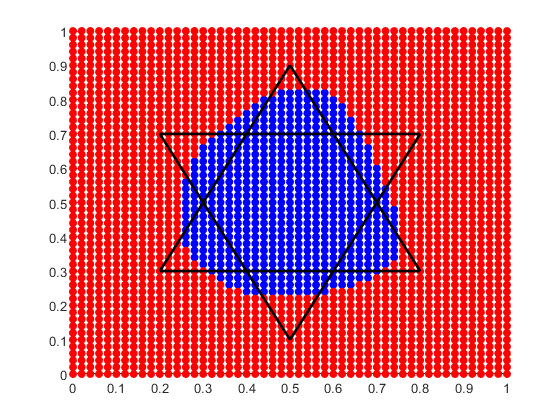

percentage_correct = 93.5794

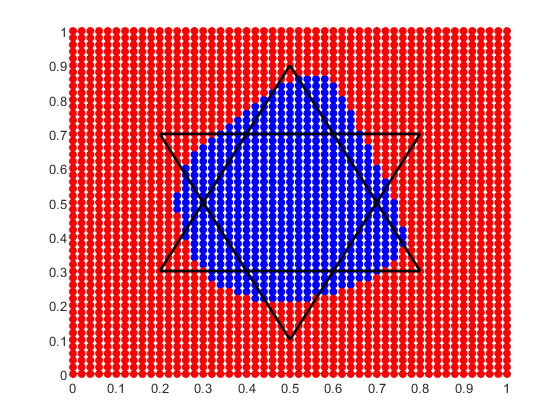

percentage_correct = 93.1180

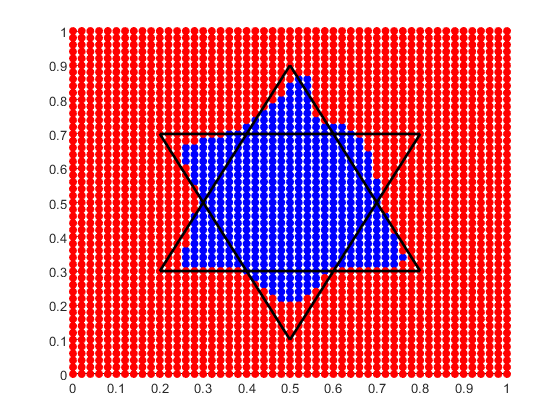

percentage_correct = 95.4633

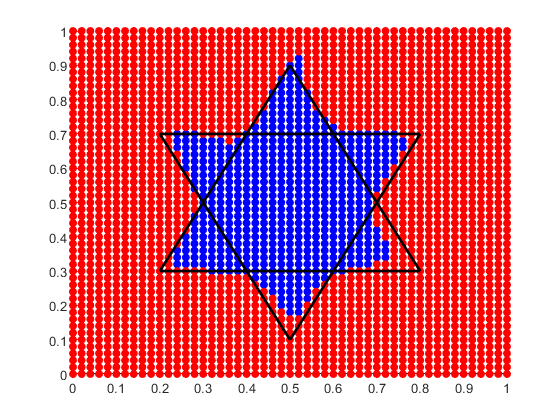

percentage_correct = 97.0012

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Ster");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

% initialize grid and variables
grid = gen_grid();
corClass = correct_classify_star(grid);

x_tot = linspace (0.2,0.8);
x1 = linspace (0.2,0.5);
x2 = linspace (0.5,0.8);
y1 = (0*x_tot) + 0.7;
y2 = -2*x1 + 1.1;
y3 = 2*x2 - 0.9;
y4 = (0*x_tot) + 0.3;
y5 = 2*x1 - 0.1;
y6 = -2*x2 + 1.9;
    
% parameters
iterations = 10^6;
batch_size= 10;
noise_params = [0, 1];
model_params = [0, 10];
step_sizes = [ 0.05 0.15 0.25 0.35];

for j = 1:length(step_sizes)
    network = NN_gen([2 7 5 3 2],'normal',model_params,5000);
    trained_network = train_net(network, data, step_sizes(j), iterations, batch_size, model_params, noise_params);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_network);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'blue','filled')
    scatter(XB,YB,'red','filled')
    plot(x_tot,y1,'black','LineWidth',2);
    plot(x1,y2,'black','LineWidth',2);
    plot(x2,y3,'black','LineWidth',2);
    plot(x_tot,y4,'black','LineWidth',2);
    plot(x1,y5,'black','LineWidth',2);
    plot(x2,y6,'black','LineWidth',2);
    hold off
    
    percentage_correct = (cor_counter/length(grid)) * 100
end